# Virtual channel conceptual

The virtual channel concept differs from the conventional method of finding a linear transformation between two devices. This script experiments with ways to demonstrate how they differ.

In words: When we find a linear transform from A to B, we always find a channel that is within the space of A to match a channel in B. If B is outside of the space spanned by A, we will find the 'closets' channel in A to a channel in B.

With the virtual channel approach, we ask whether there exists a weighted sum of the A channels (virtual-A) that is close to a weighted sum of B channels (vitual-B). Neither of these virtual channels exists in the device itself. But the two virtual channels are created as weighted sums of the real channels.

In graphics: Suppose device A has two channels. Create a 3D visualization of unit length vectors that span the color channels for device A, with the channels themselves labeled. Then show two vectors that represent the channels in a second device, B. These should be outside of the plane for device A.

We indicate the linear transform solution of how we approximate device B channels with device A data. These are weighted sums of the channels in A, and thus they are in the plane.

Then we show the intersecting virtual channel that can be reached by both a weighted sum of the channels of A and the weighted sum of the channels in B.

## Device spectral sensitivities

The devices are specified with respect to 3 wavelengths so we can render the images

% Device A
A = [1 .2; 0 1; 0 0];
for ii=1:2
    A(:,ii) = A(:,ii)/vectorLength(A(:,ii));
end

% Device B
B = [0 0.3; 1 0; .5 .7];
for ii=1:2
    B(:,ii) = B(:,ii)/vectorLength(B(:,ii));
end

intersection = estimatorNullNull(A,B);

O = [0,0,0];
lStyle = '-'; lWidth1 = 3; lWidth2 = 3;

axLim = 1.2;
alpha = .7;

## Show the plane

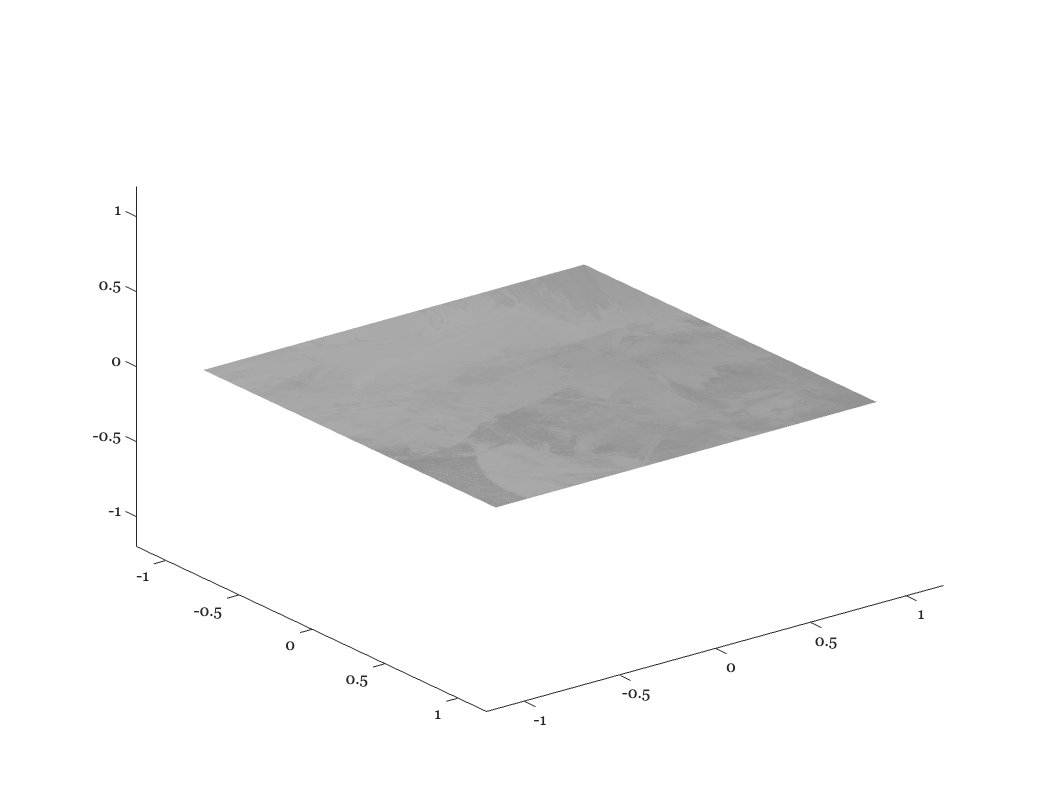

ieNewGraphWin;
set(gcf,'Position',[0.0070    0.1292    0.5727    0.7808]);

[x,y,z] = iePlaneFromVectors(A);

fname = fullfile(iefundamentalsRootPath,'fig05VirtualChannel','texture2.png');
J = imread(fname);
W1 = warp(x,y,z,J); 
W1.FaceAlpha = 0.7;
set(gca,'zlim',[-axLim axLim],'ylim',[-axLim axLim],'xlim',[-axLim axLim])
lgt1 = light("Style","Infinite","Position",[-1 1 1]);
lgt1.Position = [-10 -5 5];
lgt1.Color = [1 1 1];
lighting gouraud;

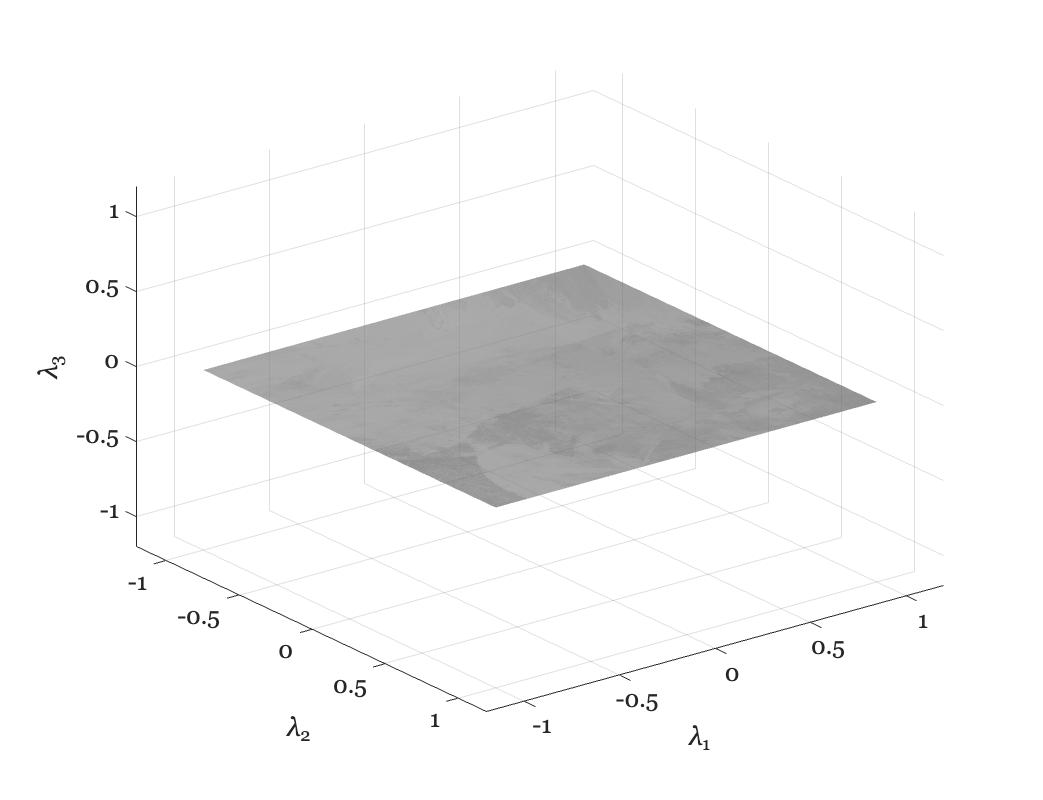

fontSize = 30;
tmp = xlabel('\lambda_1','FontSize',fontSize); 
ylabel('\lambda_2','FontSize',fontSize); 
zlabel('\lambda_3','FontSize',fontSize);
set(gca,'FontSize',24);
grid on

## Show the real channels for the first device

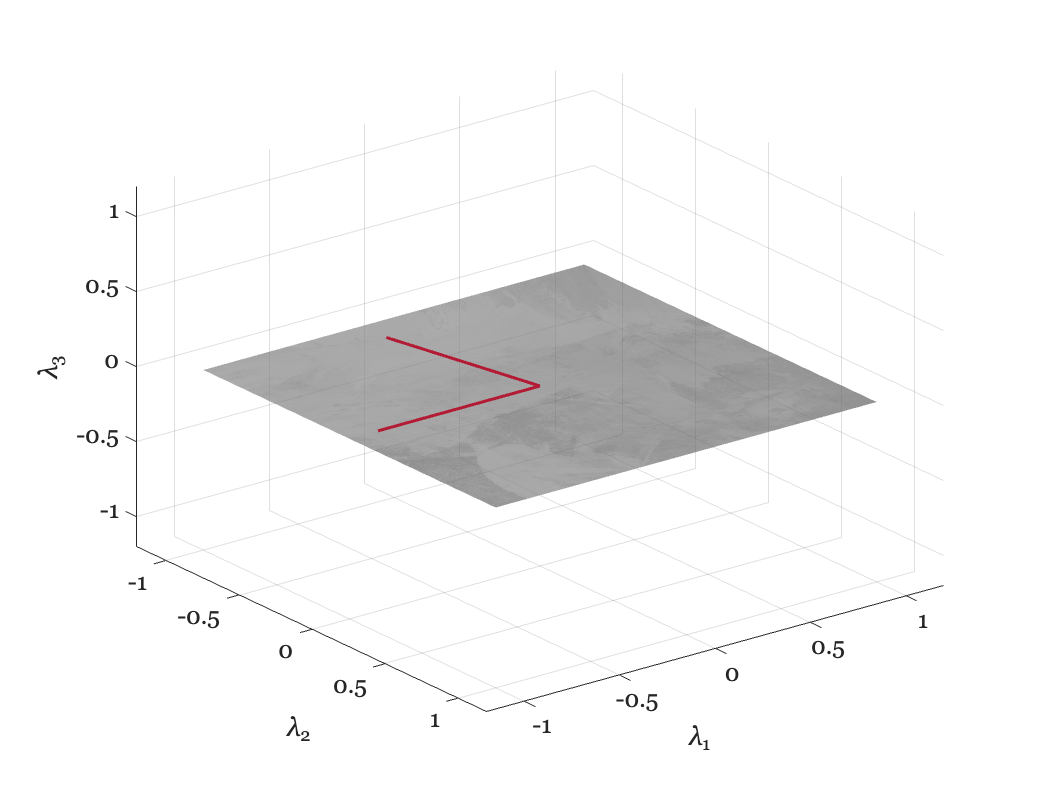

P = -0.85*A';
X = P(:, 1); Y = P(:, 2); Z = P(:, 3);
for ii=1:2
    hold on;
    %     L = quiver3(O(1), O(2), O(3), X(ii), Y(ii), Z(ii));
    deviceA(ii) = line([O(1),X(ii)],[O(2),Y(ii)],[O(3), Z(ii)]);
    deviceA(ii).LineWidth = lWidth2;
    deviceA(ii).Color = [0.7 0.1 0.2];
    deviceA(ii).LineStyle = lStyle;
end
grid on

## Show the channels for the second device

P = B';
X = P(:, 1); Y = P(:, 2); Z = P(:, 3);

for ii=1:2
    hold on;
    deviceB(ii)= line([O(1),X(ii)],[O(2),Y(ii)],[O(3), Z(ii)]); %#ok<*SAGROW>
    deviceB(ii).LineWidth = lWidth2;
    deviceB(ii).Color = [0 0.3 0.8];
    deviceB(ii).LineStyle = lStyle;
end
 
axis equal; 
set(gca,'zlim',[-axLim axLim],'ylim',[-axLim axLim],'xlim',[-axLim axLim])

view(-33,12);


## The possible channels from device B

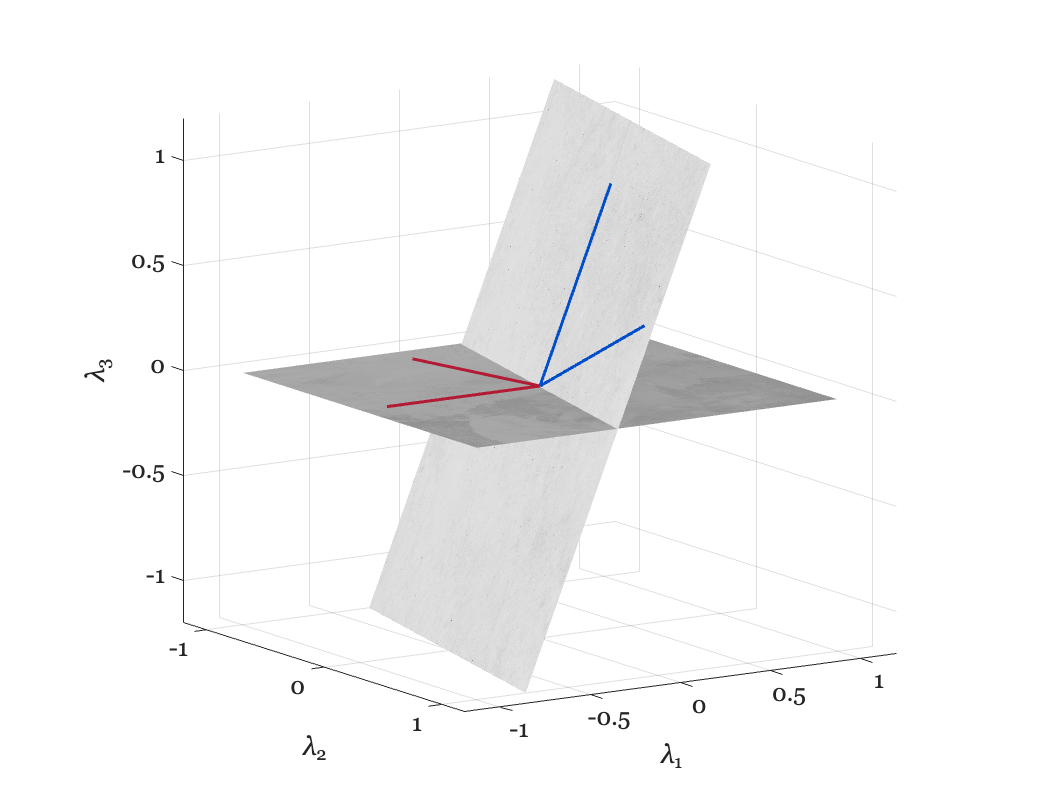

[x,y,z] = iePlaneFromVectors(B);

fname = fullfile(iefundamentalsRootPath,'fig05VirtualChannel','texture1.png');
I = imread(fname);
W = warp(x,y,z,I); W.FaceAlpha = .8;
view(-33,12);

## Show the intersection, reachable by both cameras

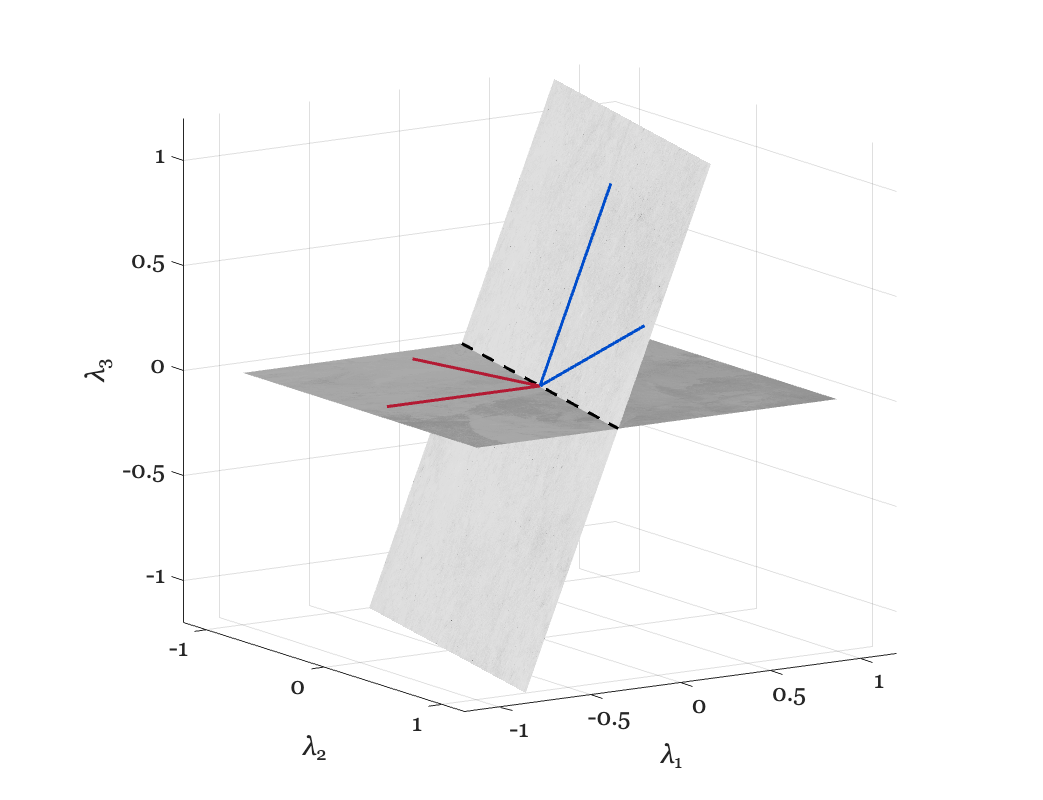

INT = line([-intersection(1),intersection(1)],[ -intersection(2),intersection(2)], [ -intersection(3), intersection(3)]);
INT.Color = 'k';
INT.LineWidth = lWidth1;
INT.LineStyle = '--';
fname = fullfile(iefundamentalsRootPath,'fig05VirtualChannel','virtualB.jpg');

deviceA(1).LineWidth = lWidth2; deviceA(2).LineWidth = lWidth2;
deviceB(1).LineWidth = lWidth2; deviceB(2).LineWidth = lWidth2;

view(-33,12);